# Optics and linearity

This calculation is designed to help you start thinking about image formation and linearity.  The idea is to consider a very simple calculation in which we have an object in the world that is made up of five different point lights.  We don't know the intensities of these lights.  

We have a very simple camera that has only some ground glass and a digital sensor.  No nice lens.  We want to sense the object light from the object with our lensless camera, and still be able to estimate the intensity of the five points.

The key concept I want you to absorb is the essential linearity of this type of system.  Such linearity plays an important role in many types of basic optics.

First, let's specify the object space image which is just 5 different points of light.  We can specify the image as a vector of five intensities

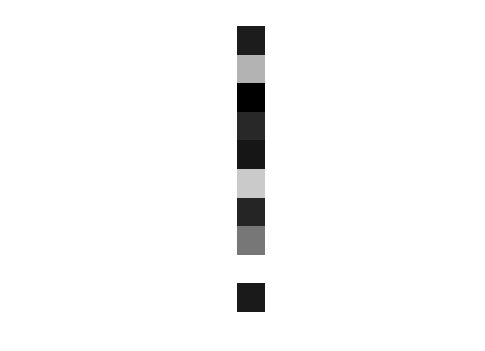

row = 64; col = 64;
% inImage = ones(5,1);
% inImage = linspace(0.2,0.9,5);

inImage = rand(10,1);
nPnts = numel(inImage);
imagesc(inImage); colormap("gray");
axis image; axis off;

Let's suppose the camera has a sensor that is 64 by 64.  In front of the sensor, we just put some scratch glass.  So the image on the sensor will be a scratchy mess.  That messy image will be different for each of the points

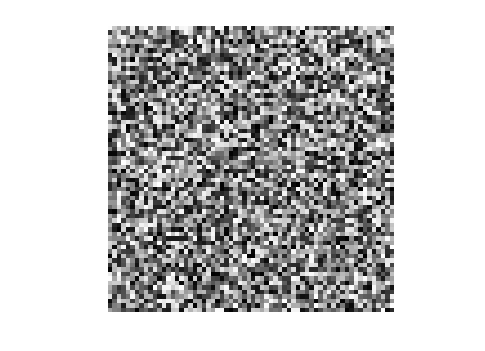


% Because the glass is scratchy, the image will be just like random
% noise.  A particular noise, but really pretty random.
% Here are the images corresponding to each of the points at an
% intensity of 1,
O = zeros(row,col,5);
for ii=1:nPnts
    O(:,:,ii) = rand(row,col,1);
end

for ii=1:nPnts
    imagesc(O(:,:,ii)); axis image; axis off;
    pause(0.1);
end

The image the we will observe from the five points is the weighted sum of the images from each of the points.  The weight is the intensity of the point.

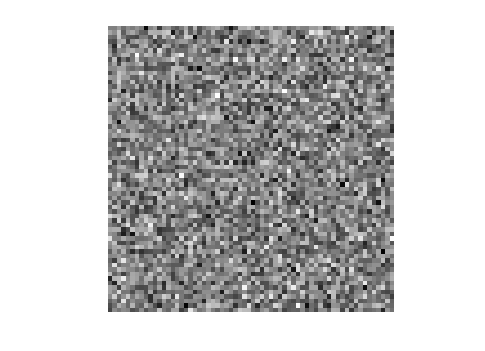

vO = reshape(O,row*col,nPnts);
output = vO*inImage(:);

imagesc(reshape(output,row,col)); 
colormap("gray"); axis off; axis image;

Estimate the input image knowing O and the output image.  We do this by vectorizing the images and solving a linear equation.

output = vO*input;

est = output\vO;

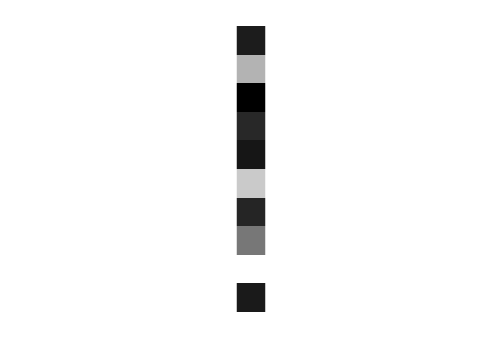

estInput = vO\output;

imagesc(estInput);axis image; axis off;

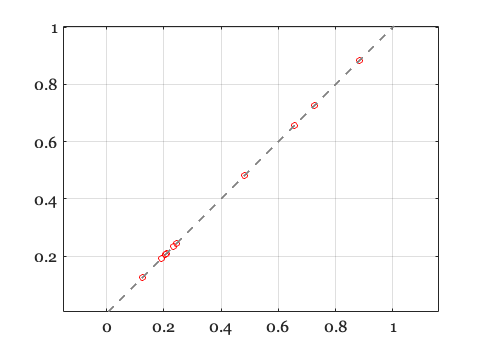

ieNewGraphWin;
plot(inImage(:),estInput(:),'o');
grid on; axis equal; identityLine;